% SELECT RANGE for IMAGESC to SHOW PIX WISE PRE PERI-STIM FRAMES BASELINE
range = input('Fig 1: from 0-1, what range values to use? Enter in bracket form with low & high end values: ') % don't need to save range var out cuz don't need it in following functions/code, just display it 

range =          0    0.0600


colorMapOrNot = input('use colormap jet or no (yes = , no = 2)?: ')

colorMapOrNot = 1

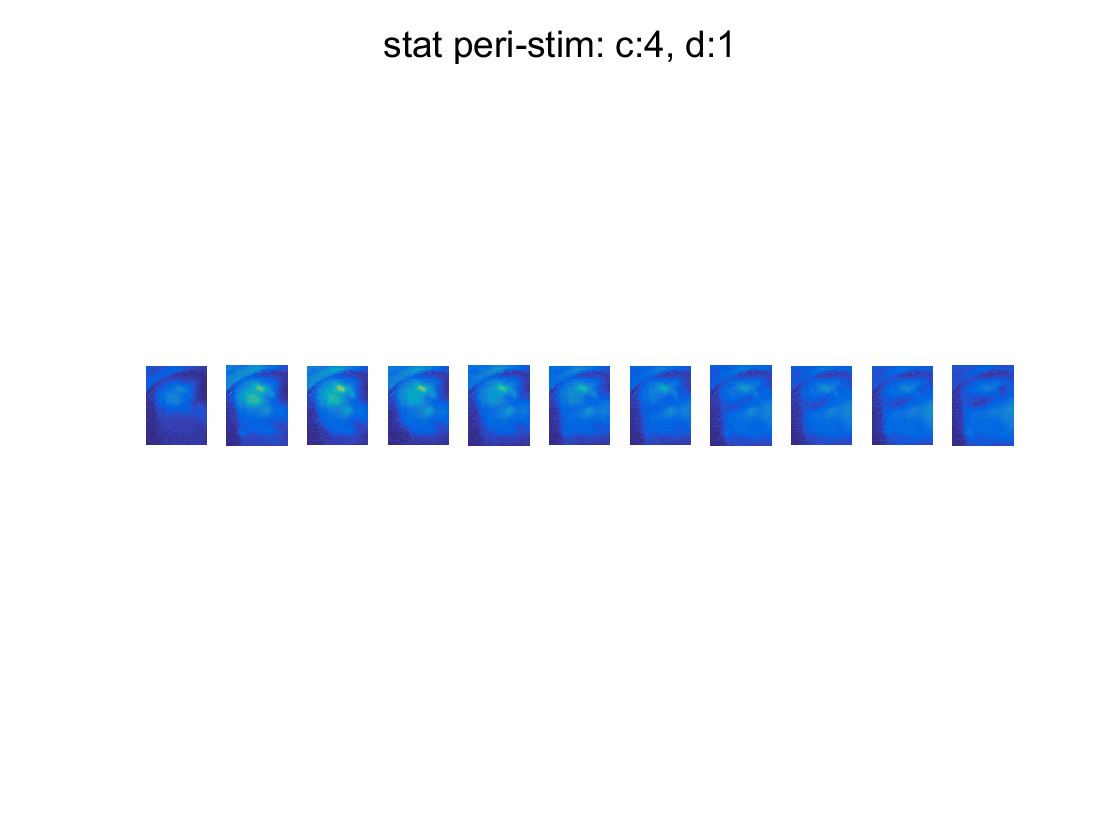

cont = 4; 
durat = 1; 

figure % one figure w/each frame as a subplot
formatSpec = 'stat peri-stim: c:%1.f, d:%1.f';
titleText = sprintf(formatSpec,cont,durat);
suptitle(titleText)

behStateTrials = idxStatTrials;

c = cont;
d = durat;

clear idxTrials
[idxTrials] = getTrials(conAndDurOrderedByTrialMeetCriteria,c,d,uniqueContrasts,uniqueDurations,behStateTrials);

for d = durat
    
    for c = cont 
        
        % for each peri-frame, plot pix wise image for selected trials
        clear f
        %for f = 1:size(onsetDf,3); % need to use size here cuz longest dim is trials, not frames for onsetDf 
        for f = stimOnsetFrame+1:size(onsetDf,3)-3 % stim onset til end of onsetDf segment
            
            % CALCULATE MEAN BASELINE IMAGE
                
            % get baseline frames, across all points, selected trials
            clear allBaselineFrames
            allBaselineFrames = onsetDf(:,:,baselineIdx,idxTrials);
            
            % take mean over frames for baseline frames of selected trials
            clear meanBaselineFrames
            meanBaselineFrames = mean(allBaselineFrames,3); % 3rd dim is frames
            meanBaselineFrames = squeeze(meanBaselineFrames);
        
            % average over trials
            clear meanBaselineImage
            meanBaselineImage = mean(meanBaselineFrames,3); % this is the "mean baseline image"
        
            %subplot(3,5,f-stimOnsetFrame+1)
            subplot(1,size(onsetDf,3)-3-stimOnsetFrame,f-stimOnsetFrame)
            
            % baseline here
            imagesc(mean(onsetDf(:,:,f,idxTrials),4)-meanBaselineImage,range) % trials defined in 1st step of this code
        
             %title(f);
             
             if colorMapOrNot == 1
                colormap jet
             end 
        
             axis off;
             axis image;
    
        end % end frames loop
    
    end % end contrast loop
    
end % end duration loop

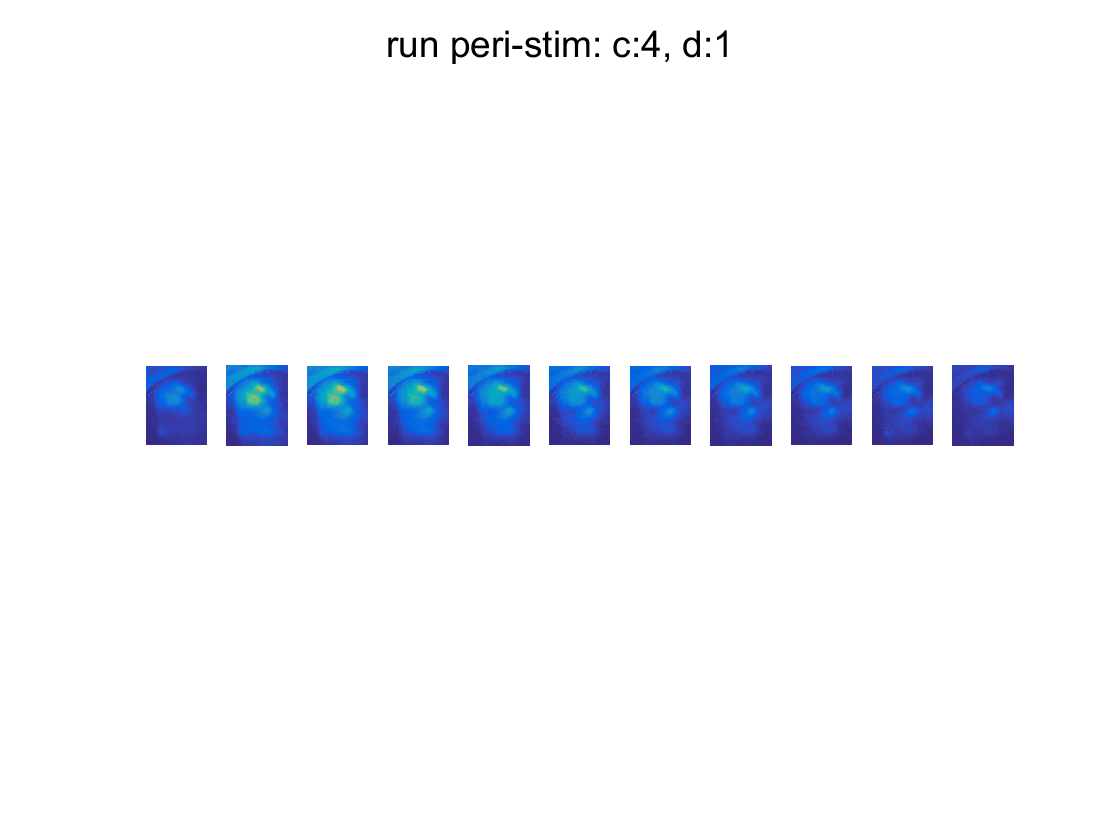

% RUN

% cont = 3; % 25% contrast
% durat = 2; % 66 ms

figure % one figure w/each frame as a subplot
formatSpec = 'run peri-stim: c:%1.f, d:%1.f';
titleText = sprintf(formatSpec,cont,durat);
suptitle(titleText)

behStateTrials = idxRunTrials;

c = cont;
d = durat;
clear idxTrials
[idxTrials] = getTrials(conAndDurOrderedByTrialMeetCriteria,c,d,uniqueContrasts,uniqueDurations,behStateTrials);

for d = durat
    
    for c = cont 
        
        % for each peri-frame, plot pix wise image for selected trials
        clear f
        %for f = 1:size(onsetDf,3); % need to use size here cuz longest dim is trials, not frames for onsetDf 
        for f = stimOnsetFrame+1:size(onsetDf,3)-3 % stim onset til end of onsetDf segment
            
            % CALCULATE MEAN BASELINE IMAGE
                
            % get baseline frames, across all points, selected trials
            clear allBaselineFrames
            allBaselineFrames = onsetDf(:,:,baselineIdx,idxTrials);
            
            % take mean over frames for baseline frames of selected trials
            clear meanBaselineFrames
            meanBaselineFrames = mean(allBaselineFrames,3); % 3rd dim is frames
            meanBaselineFrames = squeeze(meanBaselineFrames);
        
            % average over trials
            clear meanBaselineImage
            meanBaselineImage = mean(meanBaselineFrames,3); % this is the "mean baseline image"
        
            %subplot(3,5,f-stimOnsetFrame+1)
            subplot(1,size(onsetDf,3)-3-stimOnsetFrame,f-stimOnsetFrame)
            
            % baseline here
            imagesc(mean(onsetDf(:,:,f,idxTrials),4)-meanBaselineImage,range) % trials defined in 1st step of this code
        
             %title(f);
             
             if colorMapOrNot == 1
                colormap jet
             end 
        
             axis off;
             axis image;
    
        end % end frames loop
    
    end % end contrast loop
    
end % end duration loop

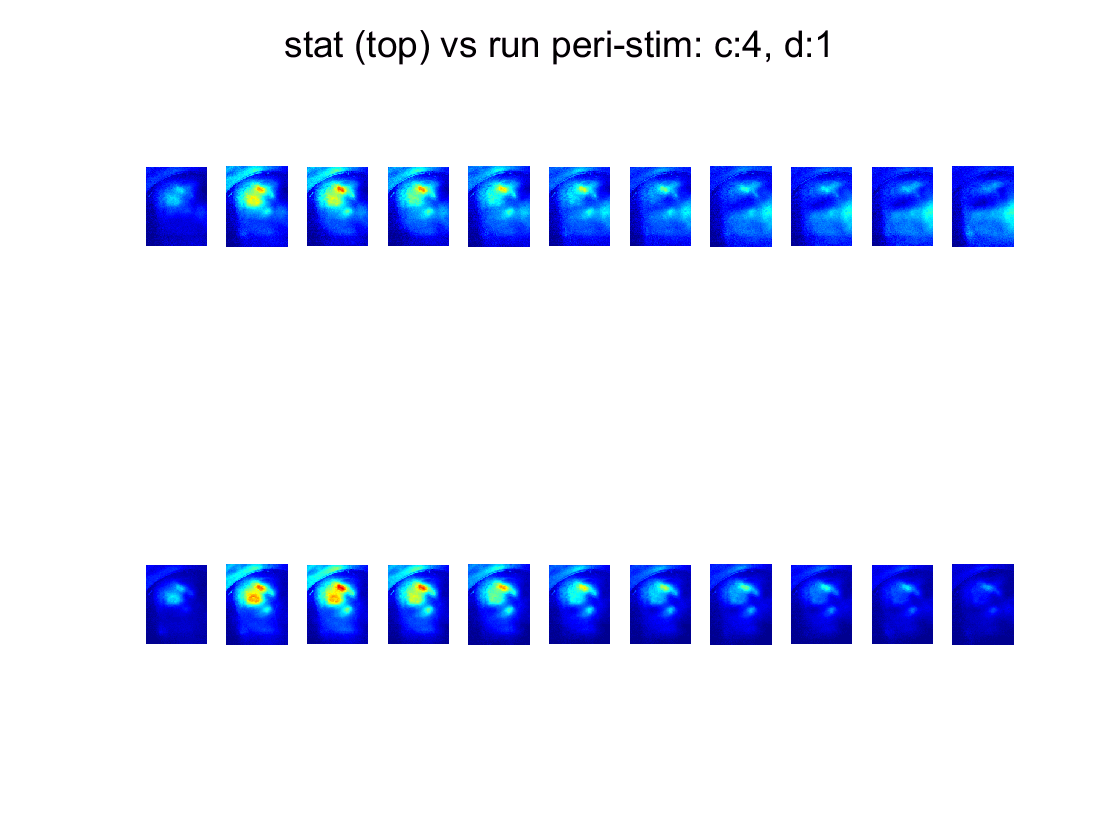

cont = 4; 
durat = 1; 

figure % one figure w/each frame as a subplot
formatSpec = 'stat (top) vs run peri-stim: c:%1.f, d:%1.f';
titleText = sprintf(formatSpec,cont,durat);
suptitle(titleText)

for d = durat
    
    for c = cont 
        
        % for each peri-frame, plot pix wise image for selected trials
        clear f
        %for f = 1:size(onsetDf,3); % need to use size here cuz longest dim is trials, not frames for onsetDf 
        for f = stimOnsetFrame+1:size(onsetDf,3)-3 % stim onset til end of onsetDf segment
            
            % GET STAT TRIALS
            clear behStateTrials
            behStateTrials = idxStatTrials;

            c = cont;
            d = durat;

            clear idxTrials
            [idxTrials] = getTrials(conAndDurOrderedByTrialMeetCriteria,c,d,uniqueContrasts,uniqueDurations,behStateTrials);

            % CALCULATE MEAN BASELINE IMAGE
                
            % get baseline frames, across all points, selected trials
            clear allBaselineFrames
            allBaselineFrames = onsetDf(:,:,baselineIdx,idxTrials);
            
            % take mean over frames for baseline frames of selected trials
            clear meanBaselineFrames
            meanBaselineFrames = mean(allBaselineFrames,3); % 3rd dim is frames
            meanBaselineFrames = squeeze(meanBaselineFrames);
        
            % average over trials
            clear meanBaselineImage
            meanBaselineImage = mean(meanBaselineFrames,3); % this is the "mean baseline image"
        
            %subplot(3,5,f-stimOnsetFrame+1)
            subplot(2,size(onsetDf,3)-3-stimOnsetFrame,f-stimOnsetFrame)
            
            % baseline here
            imagesc(mean(onsetDf(:,:,f,idxTrials),4)-meanBaselineImage,range) % trials defined in 1st step of this code
        
             if colorMapOrNot == 1
                colormap jet
             end 
        
             axis off;
             axis image;
    
        end % end frames loop
        
        hold on 
        
        % RUN

        clear behStateTrials
        behStateTrials = idxRunTrials;
        c = cont;
        d = durat;
        clear idxTrials
        [idxTrials] = getTrials(conAndDurOrderedByTrialMeetCriteria,c,d,uniqueContrasts,uniqueDurations,behStateTrials);
       
        
        % for each peri-frame, plot pix wise image for selected trials
        clear f
        %for f = 1:size(onsetDf,3); % need to use size here cuz longest dim is trials, not frames for onsetDf 
        for f = stimOnsetFrame+1:size(onsetDf,3)-3 % stim onset til end of onsetDf segment
            
            % CALCULATE MEAN BASELINE IMAGE
                
            % get baseline frames, across all points, selected trials
            clear allBaselineFrames
            allBaselineFrames = onsetDf(:,:,baselineIdx,idxTrials);
            
            % take mean over frames for baseline frames of selected trials
            clear meanBaselineFrames
            meanBaselineFrames = mean(allBaselineFrames,3); % 3rd dim is frames
            meanBaselineFrames = squeeze(meanBaselineFrames);
        
            % average over trials
            clear meanBaselineImage
            meanBaselineImage = mean(meanBaselineFrames,3); % this is the "mean baseline image"
        
            %subplot(3,5,f-stimOnsetFrame+1)
            subplot(2,size(onsetDf,3)-3-stimOnsetFrame,f-stimOnsetFrame+(size(onsetDf,3)-3-stimOnsetFrame))
            
            % baseline here
            imagesc(mean(onsetDf(:,:,f,idxTrials),4)-meanBaselineImage,range) % trials defined in 1st step of this code
        
             %title(f);
             
             if colorMapOrNot == 1
                colormap jet
             end 
        
             axis off;
             axis image;
    
        end % end frames loop
    
    end % end contrast loop
    
end % end duration loop